Teniendo en cuenta los valores articulares listados a continuacion, se calcula por medio de diferentes metodos los valores de posición y de orientación en coordenadas generalizadas del efector final.

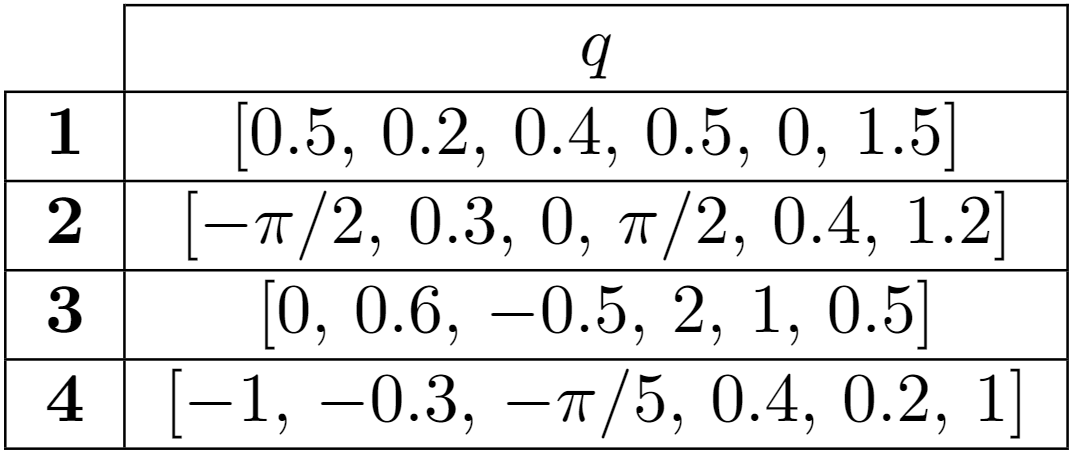

Hallando las MTH de cada eslabón de manera simbólica se procede a multiplicarlas entre sí para obtener la matriz MTH desde la base hasta el efector final en terminos de los valores articulares del robot.

threshold = 1e-8;
syms theta1 theta2 theta3 theta4 theta5 theta6
MTH_01 = mapSymType(L(1).A(theta1),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_12 = mapSymType(L(2).A(theta2),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_23 = mapSymType(L(3).A(theta3),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_34 = mapSymType(L(4).A(theta4),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_45 = mapSymType(L(5).A(theta5),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_56 = mapSymType(L(6).A(theta6),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH_6T = Robot.tool;
MTH_0T = MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*MTH_6T;
MTH_0T = simplify(MTH_0T);

Teniendo en cuenta que se desea obtener la orientación del efector final en ángulos fijos $\left(\phi \left(\textrm{roll}\right),\theta \;\left(\textrm{pitch}\right),\psi \;\left(\textrm{yaw}\right)\right)$ se tiene que el modelo de la MTH del efector final respecto a la base es el siguiente:

syms phi theta psi x y z

MTH_Robot2 = transl(x,y,z)*trotz(psi)*troty(theta)*trotx(phi)

$$MTH\_Robot2 = \left(\begin{array}{cccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & x\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & y\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Con los elementos de la matriz anterior es posible despejar las variables de posición y orientación del efector final así:


$$x={{\textrm{MTH}}^{0T} }_{1,4}$$



$$y={{\textrm{MTH}}^{0T} }_{2,4}$$



$$z={{\textrm{MTH}}^{0T} }_{3,4}$$



$$\phi =\tan^{-1} \left(\frac{{{\textrm{MTH}}^{0T} }_{3,2} }{{{\textrm{MTH}}^{0T} }_{3,3} }\right)$$



$$\theta =\sin^{-1} \left({{-\textrm{MTH}}^{0T} }_{3,1} \right)$$



$$\psi =\tan^{-1} \left(\frac{{{\textrm{MTH}}^{0T} }_{2,1} }{{{\textrm{MTH}}^{0T} }_{1,1} }\right)$$


x = simplify(MTH_0T(1,4));
y = simplify(MTH_0T(2,4));
z = simplify(MTH_0T(3,4));
theta = simplify(asin(-MTH_0T(3,1)));
phi = simplify(atan2(MTH_0T(3,2),MTH_0T(3,3)));
psi = atan2(MTH_0T(2,1),MTH_0T(1,1));

De esta manera, basta con hallar el valor númerico de la matriz MTH del efector final a la base con los valores articulares dados y hallar los valores de posición y orientación en cada configuración.

q1 = [0.5,0.2,0.4,0.5,0,1.5];
q2 = [-pi/2,0.3,0,pi/2,0.4,1.2];
q3 = [0,0.6,-0.5,2,1,0.5];
q4 = [-1,-0.3,-pi/5,0.4,0.2,1];

MTH_Robot1 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q1));
x = MTH_Robot1(1,4);
y = MTH_Robot1(2,4);
z = MTH_Robot1(3,4);
theta = asin(-MTH_Robot1(3,1));
phi = atan2(MTH_Robot1(3,2),MTH_Robot1(3,3));
psi = atan2(MTH_Robot1(2,1),MTH_Robot1(1,1));
X1= [x;y;z;phi;theta;psi]'

X1 =   458.8531  250.6726  967.7821   -0.9258    0.3506   -0.8179


MTH_Robot2 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q2));
x = MTH_Robot2(1,4);
y = MTH_Robot2(2,4);
z = MTH_Robot2(3,4);
theta = asin(-MTH_Robot2(3,1));
phi = atan2(MTH_Robot2(3,2),MTH_Robot2(3,3));
psi = atan2(MTH_Robot2(2,1),MTH_Robot2(1,1));
X2= [x;y;z;phi;theta;psi]'

X2 =   -31.1535 -554.2512  815.2438   -0.7204    1.2002   -2.7428


MTH_Robot3 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q3));
x = MTH_Robot3(1,4);
y = MTH_Robot3(2,4);
z = MTH_Robot3(3,4);
theta = asin(-MTH_Robot3(3,1));
phi = atan2(MTH_Robot3(3,2),MTH_Robot3(3,3));
psi = atan2(MTH_Robot3(2,1),MTH_Robot3(1,1));
X3= [x;y;z;phi;theta;psi]'

X3 =   460.0481  -61.2118  639.6002   -1.9982    0.7808   -2.8094


MTH_Robot4 = double(subs(MTH_0T,[theta1 theta2 theta3 theta4 theta5 theta6],q4));	
x = MTH_Robot4(1,4);
y = MTH_Robot4(2,4);
z = MTH_Robot4(3,4);
theta = asin(-MTH_Robot4(3,1));
phi = atan2(MTH_Robot4(3,2),MTH_Robot4(3,3));
psi = atan2(MTH_Robot4(2,1),MTH_Robot4(1,1));
X4= [x;y;z;phi;theta;psi]'

X4 =   305.1279 -486.6637  246.2073   -2.3274   -0.1829   -2.5058


#### Los resultados obtenidos se reunen en la siguiente tabla:

#### 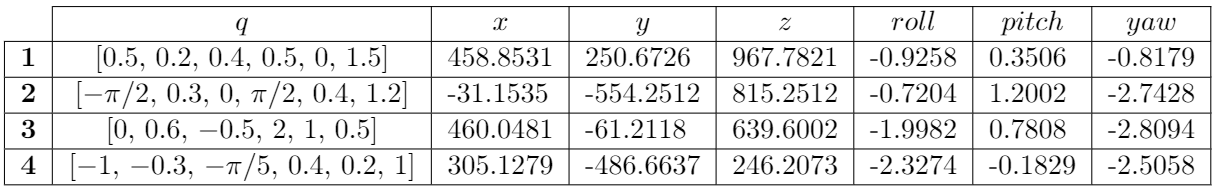

**Peter corke**

PMTH=Robot.fkine(q1);
X1=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X1 =   458.8531  250.6726  967.7821   -0.9258    0.3506   -0.8179


PMTH=Robot.fkine(q2);
X2=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X2 =   -31.1535 -554.2512  815.2438   -0.7204    1.2002   -2.7428


PMTH=Robot.fkine(q3);
X3=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X3 =   460.0481  -61.2118  639.6002   -1.9982    0.7808   -2.8094


PMTH=Robot.fkine(q4);
X4=[transl(PMTH);flip(tr2rpy(PMTH,'zyx')')]'

X4 =   305.1279 -486.6637  246.2073   -2.3274   -0.1829   -2.5058


**RST**

c1 = num2cell(q1);
c2 = num2cell(q2);
c3 = num2cell(q3);
c4 = num2cell(q4);
s = homeConfiguration(robotRST);
[s.JointPosition] = c1{:};
tform = getTransform(robotRST,s,'endeffector','base');
X1=[tform2trvec(tform)';flip(tform2eul(tform)')]'

X1 =   458.8531  250.6726  967.7821   -0.9258    0.3506   -0.8179


[s.JointPosition] = c2{:};
tform = getTransform(robotRST,s,'endeffector','base');
X2=[tform2trvec(tform)';flip(tform2eul(tform)')]'

X2 =   -31.1535 -554.2512  815.2438   -0.7204    1.2002   -2.7428


[s.JointPosition] = c3{:};
tform = getTransform(robotRST,s,'endeffector','base');
X3=[tform2trvec(tform)';flip(tform2eul(tform)')]'

X3 =   460.0481  -61.2118  639.6002   -1.9982    0.7808   -2.8094


[s.JointPosition] = c4{:};
tform = getTransform(robotRST,s,'endeffector','base');
X4=[tform2trvec(tform)';flip(tform2eul(tform)')]' 

X4 =   305.1279 -486.6637  246.2073   -2.3274   -0.1829   -2.5058


Como se mostró anteriormente se llega a los mismos resultados utilizando los tres métodos implementados de cinemática directa, es importante mencionar que para el caso del Toolbox de Peter Corke se debe configurar la convención de las rotaciones en ángulos fijos con el valor 'zyx'. Esta es la configuración por defecto en el Robotics Systems Toolbox, por lo que se omite este parámetro. En las funciones de ambos Toolbox se debe invertir el orden del vector para poder expresar la orientación primero respecto al eje "x", luego el eje "y" y finalmente el eje "z".					

Se desarrolla una GUI que permite mover cada articulación mediante controles de tipo Slider y asimismo permite visualizar el robot y la posición del efector final.

Por medio de esta interfaz se comprueban los valores de posición y orientacion del efector final para cada una de las configuraciones planteadas anteriormente.